a)

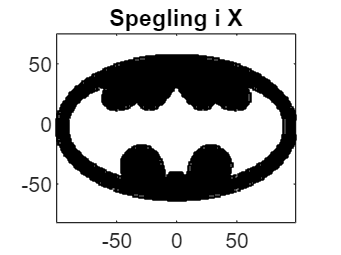

data = load('batman.mat');
data1 = data.B(1, : );
data2 = data.B(2, :);
spegling = [1, 0; 0, -1] * data.B;
plot(spegling(1, :), spegling(2, :), 'k.', 'MarkerSize', 1)
axis equal
title("Spegling i X")

b)

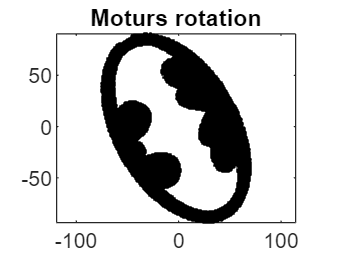

radianer = 120 * pi / 180;
A = [cos(radianer), -sin(radianer);
    sin(radianer), cos(radianer)];
rotation = A * data.B;

plot(rotation(1, :), rotation(2, :) ,'k.','MarkerSize', 1)
axis equal
title("Moturs rotation")

c)

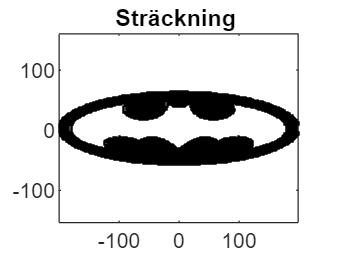

stretch = data1 * 2;
plot(stretch, data2, 'k.', 'MarkerSize', 1)
axis equal
title("Sträckning ")

d)

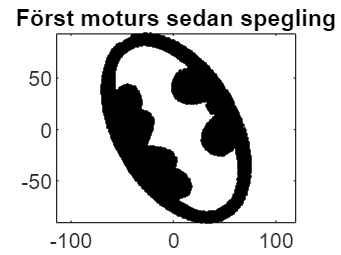

radianer = 60 * pi / 180;
A = [cos(radianer), -sin(radianer);
    sin(radianer), cos(radianer)];

rotation = A * data.B;
spegling = [-1, 0; 0, 1] * rotation;

plot(spegling(1, :), spegling(2, :) ,'k.','MarkerSize', 1)
axis equal
title("Först moturs sedan spegling")

e)